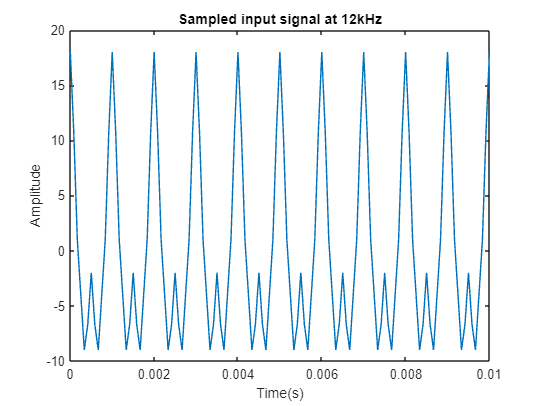

% Given parameters
Fs = 12000; %Sampling frequency
T = 0.2;
t = 0:1/Fs:T;
f = 1000;

%Given signal
x = 10*cos(2*pi*f*t)+6*cos(2*pi*2*f*t)+2*cos(2*pi*4*f*t);

%Plot
figure(1)
plot(t, x)
title('Sampled input signal at 12kHz')
xlabel('Time(s)')
ylabel('Amplitude')
xlim([0,0.01])

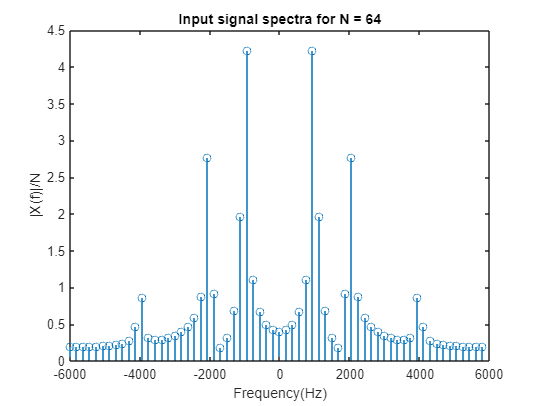


%Signal spectra

%For N=64
N=64;
f=Fs/N*(-N/2:N/2-1);
X = fft(x, N);
X = fftshift(X);
X = abs(X);
figure(2)
stem(f, X/N)
title('Input signal spectra for N = 64')
xlabel('Frequency(Hz)')
ylabel('|X(f)|/N')

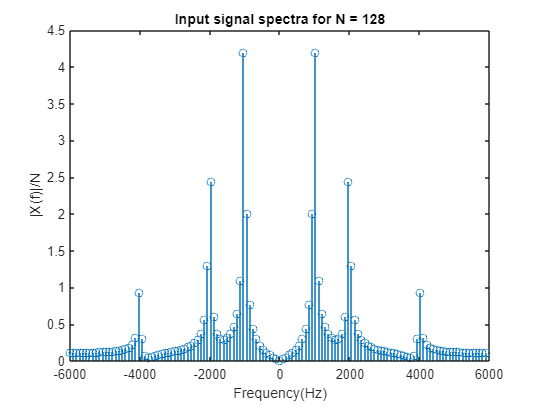


%For N=128
N=128;
f=Fs/N*(-N/2:N/2-1);
X = fft(x, N);
X = fftshift(X);
X = abs(X);
figure(3)
stem(f, X/N)
title('Input signal spectra for N = 128')
xlabel('Frequency(Hz)')
ylabel('|X(f)|/N')

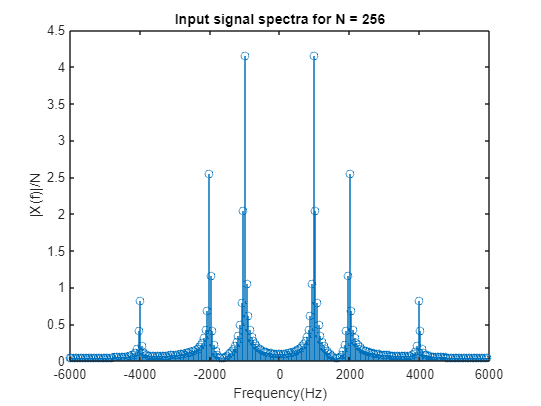


%For N=256
N=256;
f=Fs/N*(-N/2:N/2-1);
X = fft(x, N);
X = fftshift(X);
X = abs(X);
figure(4)
stem(f, X/N)
title('Input signal spectra for N = 256')
xlabel('Frequency(Hz)')
ylabel('|X(f)|/N')